# Problem 2

addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);

AU = 1.496e+8;
R_E = 6378.1363;
mu_E = 398600.4415;
R_I = 5500;
mu_I = 2e5;
mu_S = 132712440017.99;
global iCr

1 - Earth Departure 

[no subscript] - Iota Arrival

0 - Pre-maneuver/assist

n - Post-maneuver/assist

E - Earth

I - Iota

Iota Orbit Characterisics @ Arrival (Heliocentric)

a_I = 3*AU

a_I = 448800000

e_I = 0.3

e_I = 0.3000

p_I = a_I * (1-e_I^2)

p_I = 408408000

ta_I = deg2rad(120)

ta_I = 2.0944

r_mag = a_I * (1-e_I^2) / (1+e_I*cos(ta_I))

r_mag = 4.8048e+08

v_I_mag = sqrt(mu_S*(2/r_mag - 1/a_I))

v_I_mag = 16.0222

h_I = sqrt(mu_S * p_I)

h_I = 7.3621e+09

gamma_I = acos(h_I/r_mag/v_I_mag),gamma_I_deg = rad2deg(gamma_I)

gamma_I = 0.2966

gamma_I_deg = 16.9961

v_I_R = v_I_mag * [sin(gamma_I);cos(gamma_I)]

v_I_R =     4.6834
   15.3224


v_I = iCr * v_I_R

v_I =    -1.4604
  -15.9555


Transfer Orbit @ Arrival (Heliocentric)

v_0_mag = 14

v_0_mag = 14

gamma_0 = deg2rad(-5)

gamma_0 = -0.0873

a_0 = (2/r_mag - v_0_mag^2/mu_S)^-1

a_0 = 3.7235e+08

v_0_R = v_0_mag * [sin(gamma_0);cos(gamma_0)]

v_0_R =    -1.2202
   13.9467


rvs_0 = r_mag*v_0_mag^2/mu_S

rvs_0 = 0.7096

e_0 = sqrt((rvs_0 - 1)^2 * cos(gamma_0)^2 + sin(gamma_0)^2)

e_0 = 0.3021

ta_0 = -acos(1/e_0*(a_0*(1-e_0^2)/r_mag - 1))+2*pi, ta_0_deg = rad2deg(ta_0)

ta_0 = 3.3470

ta_0_deg = 191.7665

iCr = [cos(ta_0) -sin(ta_0); sin(ta_0) cos(ta_0)]

iCr =    -0.9790    0.2039
   -0.2039   -0.9790


v_0 = iCr * v_0_R

v_0 =     4.0386
  -13.4048


Hyperbolic Orbit (Iota Centric)

v_inf_0 = v_0 - v_I

v_inf_0 =     5.4990
    2.5507


v_inf_mag = norm(v_inf_0)

v_inf_mag = 6.0617


a_h = -mu_I/v_inf_mag^2

a_h = -5.4430e+03

eta = asin(v_0_mag/v_inf_mag * sin(abs(gamma_I)+abs(gamma_0))), eta_deg = rad2deg(eta)

eta = 1.0452

eta_deg = 59.8864


G = pi - eta - gamma_I

G = 1.7997

sigma = pi - G

sigma = 1.3419

lamda = asin(v_I_mag/v_inf_mag * sin(gamma_I)), lamda_deg = rad2deg(lamda)

lamda = 0.8829

lamda_deg = 50.5893

delta = pi - lamda - sigma, delta_deg = rad2deg(delta)

delta = 0.9168

delta_deg = 52.5282


e_h = 1/sin(delta/2)

e_h = 2.2598

b_h = - a_h * sqrt(e_h^2-1)

b_h = 1.1030e+04

## Part b)

v_n_mag = v_inf_mag*sin(eta+delta)/sin(gamma_I)

v_n_mag = 19.1709

v_n_R = v_n_mag *[0 1]'

v_n_R =          0
   19.1709


v_n = iCr * v_n_R

v_n =     3.9094
  -18.7680


dv_eq = v_n - v_0

dv_eq =    -0.1292
   -5.3632


dv_eq_mag = norm(dv_eq)

dv_eq_mag = 5.3648

gamma_n = 0

gamma_n = 0

energy_n = v_n_mag^2/2 - mu_S/r_mag

energy_n = -92.4467

a_n = -mu_S/2/energy_n

a_n = 7.1778e+08

rvs_n = r_mag*v_n_mag^2/mu_S

rvs_n = 1.3306

e_n = sqrt((rvs_n - 1)^2 * cos(gamma_n)^2 + sin(gamma_n)^2)

e_n = 0.3306

ta_n = atan((rvs_n*cos(gamma_n)^2+sin(gamma_n)^2)/(rvs_n*cos(gamma_n)^2)-1)

ta_n = 0

ta_n = acos(1/e_n*(a_n*(1-e_n^2)/r_mag - 1))

ta_n = 0

n_n = sqrt(mu_S/a_n^3)

n_n = 1.8944e-08

% rp_n = a_n*(1-e_n)
% vp_n = sqrt(mu_S*(2/rp_n - 1/a_n))
% ra_n = a_n*(1+e_n)
% va_n = sqrt(mu_S*(2/ra_n - 1/a_n))
period = 2*pi/n_n, period_day = period/3600/24

period = 3.3167e+08

period_day = 3.8388e+03

zeta = asin(v_I_mag/v_0_mag * sin(eta)),zeta_deg = rad2deg(zeta)

zeta = 1.4291

zeta_deg = 81.8825

beta = pi-asin(v_n_mag/dv_eq_mag * sin(abs(gamma_0))),beta_deg = rad2deg(beta)

beta = 2.8249

beta_deg = 161.8534

alpha = asin(v_n_mag/dv_eq_mag * sin(abs(gamma_0))), alpha_deg = rad2deg(alpha)

alpha = 0.3167

alpha_deg = 18.1466

h_n = sqrt(mu_S * a_n * (1-e_n^2))

h_n = 9.2112e+09

## Part c)

ta_inf = acos(-1/e_h)

ta_inf = 2.0292

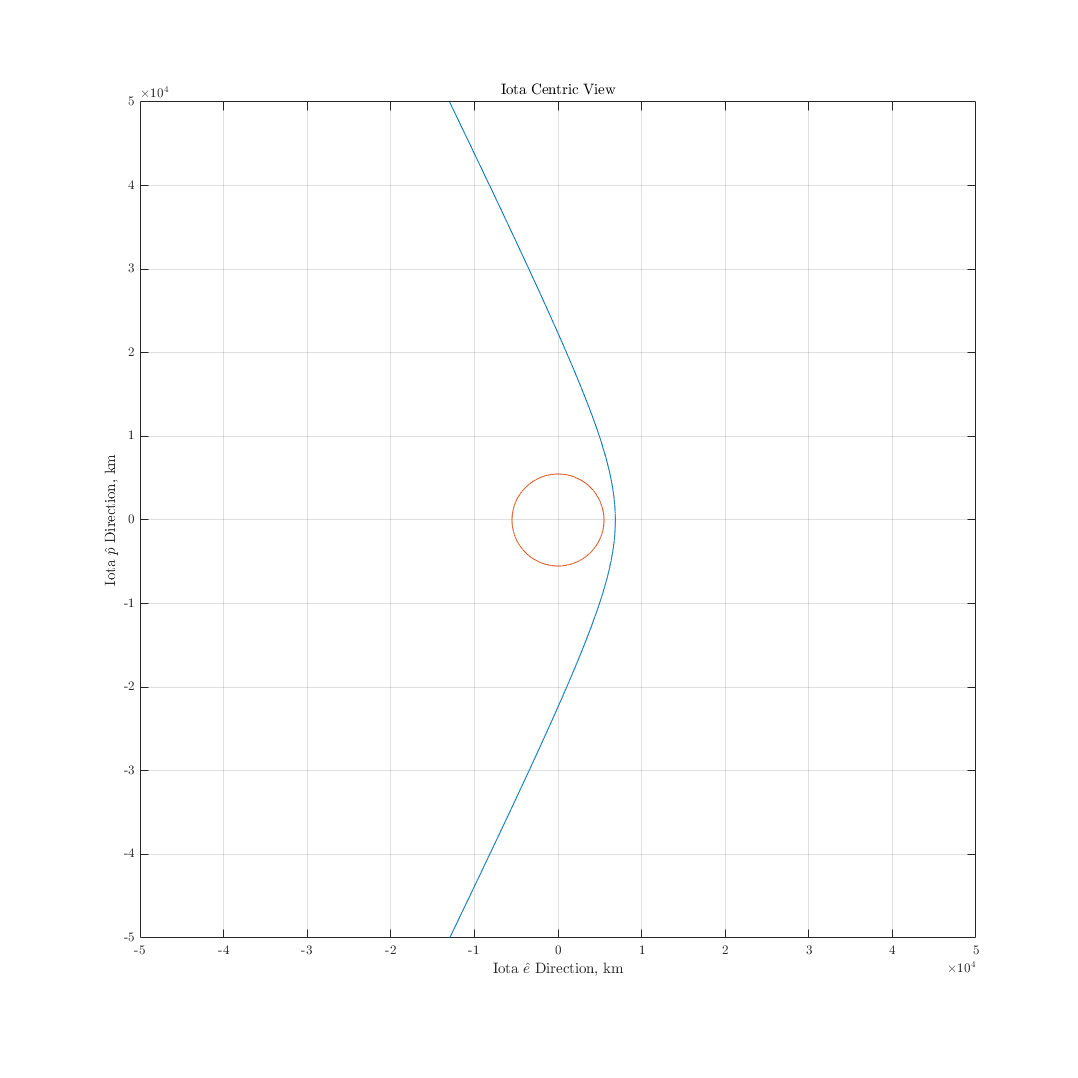


plotorbit(a_h,e_h,-ta_inf,ta_inf,0)
hold on
plotorbit(R_I,0,0,2*pi,0)
xlim([-1,1]*5e4),ylim([-1,1]*5e4)
title('Iota Centric View')
xlabel('Iota $\hat{e}$ Direction, km')
ylabel('Iota $\hat{p}$ Direction, km')
set(gcf,'position',[0,0,1200,1200])
hold off

## Part d)

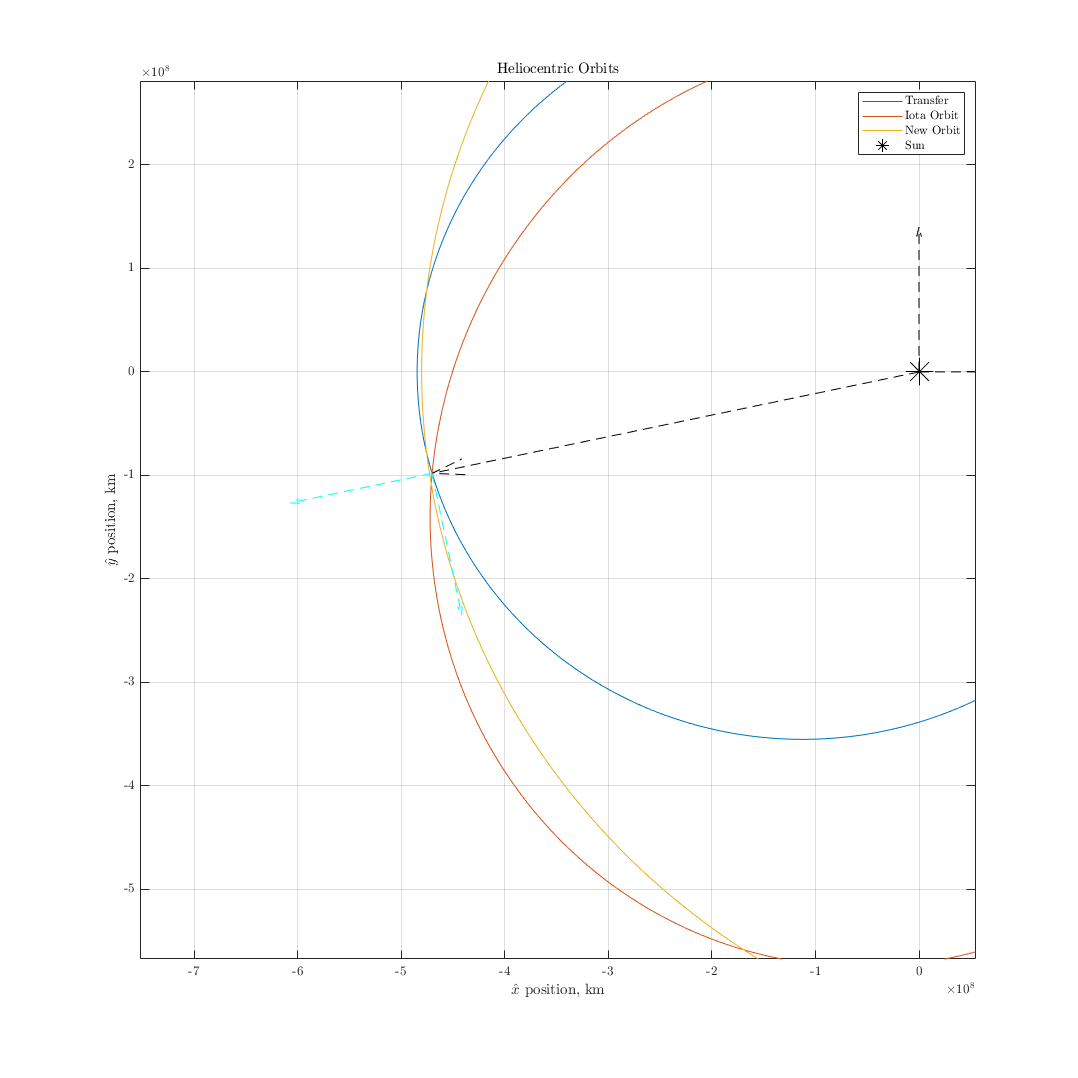

plotorbit(a_0,e_0,0,2*pi,0)
hold on
plotorbit(a_I,e_I,0,2*pi,ta_I-ta_0)
xlim([-.6 1.2]*1e9),ylim([-1 1]*1e9)
axis equal
plotorbit(a_n,e_n,0,2*pi,pi)
plot(0,0,'k*',"MarkerSize",20)
plotpos(a_0,e_0,ta_0,'k--',0,2e4)
plotunit([0,0],0,'k--',2e4)
legend('Transfer','Iota Orbit','New Orbit','Sun')
title('Heliocentric Orbits')
xlabel('$\hat{x}$ position, km')
ylabel('$\hat{y}$ position, km')